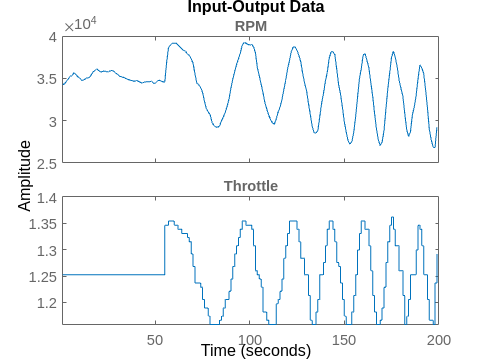

data = ulogreader("log_0_2023-3-27-17-28-24.ulg");
start_time = data.StartTime;
end_time = data.EndTime;
load('ESC_RPM.mat')
load('ESC_throttle.mat')
n = length(ESC_throttle.Throttle)-1;
step = seconds(seconds(end_time-start_time)/n);
time_t = (start_time:step:end_time)';
t_start = duration('00:03:38.946086');
t_end_s = duration('00:03:59.169274');
throttle_m = timetable(time_t,ESC_throttle.Throttle,'VariableNames',{'throttle_m'}); 
rpm_m = timetable(time_t,ESC_RPM.Speed,'VariableNames',{'rpm_m'}); 
ts_range = timerange(t_start, t_end_s);
u = double(throttle_m.throttle_m(ts_range,:));
y = double(rpm_m.rpm_m(ts_range,:));
np = 2;
nz = 1;
iodelay = 0;
data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'RPM'})
plot(data)

sys1= tfest(data,np,nz,iodelay)

sys1 =
  From input "Throttle" to output "RPM":
     8.057e04 s - 56.35
  ------------------------
  s^2 + 1.63 s + 2.402e-08
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 53.08%                   
FPE: 2.445e+06, MSE: 2.302e+06                   
 
Model Properties


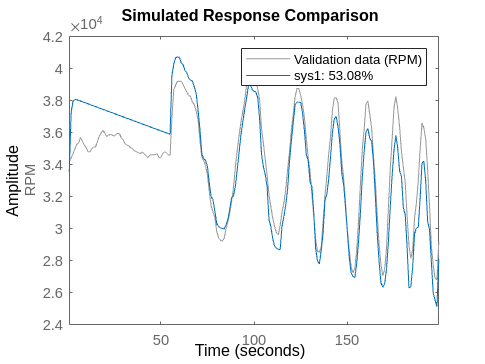

compare(data,sys1)